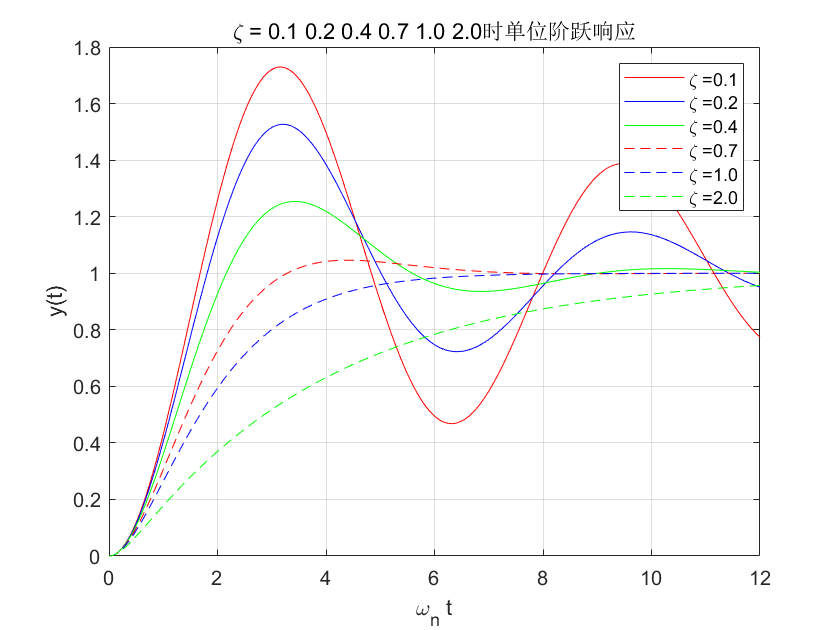

clear
t = [0:0.01:12];
num = [1];
zeta1 = 0.1;
den1 = [1 2*zeta1 1];
sys1 = tf(num, den1);
 
zeta2 = 0.2;
den2 = [1 2*zeta2 1];
sys2 = tf(num, den2);

zeta3 = 0.4;
den3 = [1 2*zeta3 1];
sys3 = tf(num, den3);

zeta4 = 0.7;
den4 = [1 2*zeta4 1];
sys4 = tf(num, den4);

zeta5 = 1.0;
den5 = [1 2*zeta5 1];
sys5 = tf(num, den5);

zeta6 = 2.0;
den6 = [1 2*zeta6 1];
sys6 = tf(num, den6);

[y1, T1] = step(sys1,t);
[y2, T2] = step(sys2,t);
[y3, T3] = step(sys3,t);
[y4, T4] = step(sys4,t);
[y5, T5] = step(sys5,t);
[y6, T6] = step(sys6,t);

plot(T1,y1,'r-',T2,y2,'b-',T3,y3,'g-',T4,y4,'r--',T5,y5,'b--',T6,y6,'g--')
xlabel('\omega_n t'),ylabel('y(t)');
title('\zeta = 0.1 0.2 0.4 0.7 1.0 2.0时单位阶跃响应'),grid on;
legend('\zeta =0.1','\zeta =0.2','\zeta =0.4','\zeta =0.7','\zeta =1.0','\zeta =2.0')

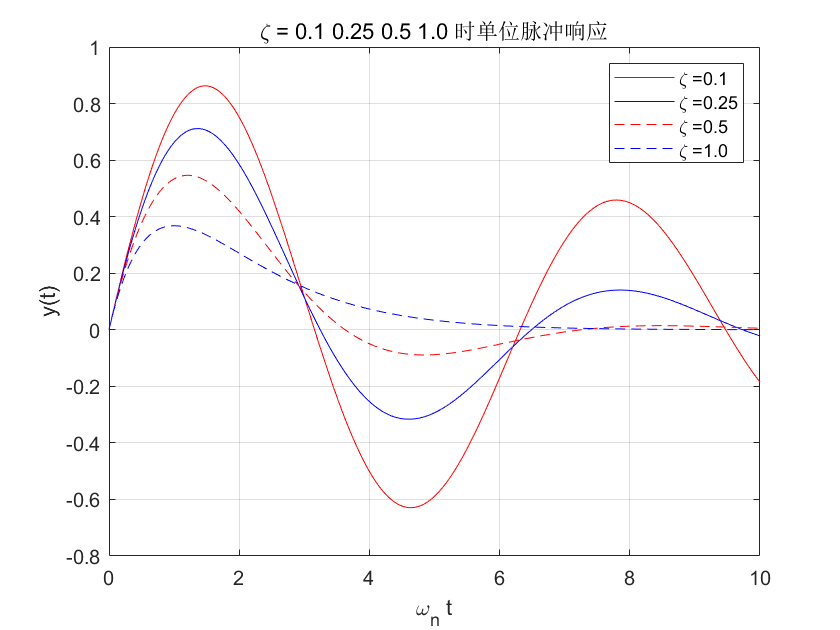

clear
t = [0:0.01:10];
num = [1];
zeta1 = 0.1;
den1 = [1 2*zeta1 1];
sys1 = tf(num,den1);

zeta2 = 0.25;
den2 = [1 2*zeta2 1];
sys2 = tf(num,den2);

zeta3 = 0.5;
den3 = [1 2*zeta3 1];
sys3 = tf(num,den3);

zeta4 = 1.0;
den4 = [1 2*zeta4 1];
sys4 = tf(num,den4);

[y1,T1] = impulse(sys1,t);
[y2,T2] = impulse(sys2,t);
[y3,T3] = impulse(sys3,t);
[y4,T4] = impulse(sys4,t);

plot(T1,y1,'r-',T2,y2,'b-',T3,y3,'r--',T4,y4,'b--');
xlabel('\omega_n t'),ylabel('y(t)');
title('\zeta = 0.1 0.25 0.5 1.0 时单位脉冲响应'),grid on;
legend('\zeta =0.1','\zeta =0.25','\zeta =0.5','\zeta =1.0')

clear
numg = [10 20];
deng = [1 10 0];
sysg = tf(numg,deng);
[sys]= feedback(sysg,[1]);
t = [0:0.1:8.2]';
v1 = [0:0.1:2]';
v2 = [2:-0.1:-2]';
v3 = [-2:0.1:0]';
u = [v1;v2;v3]

u =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


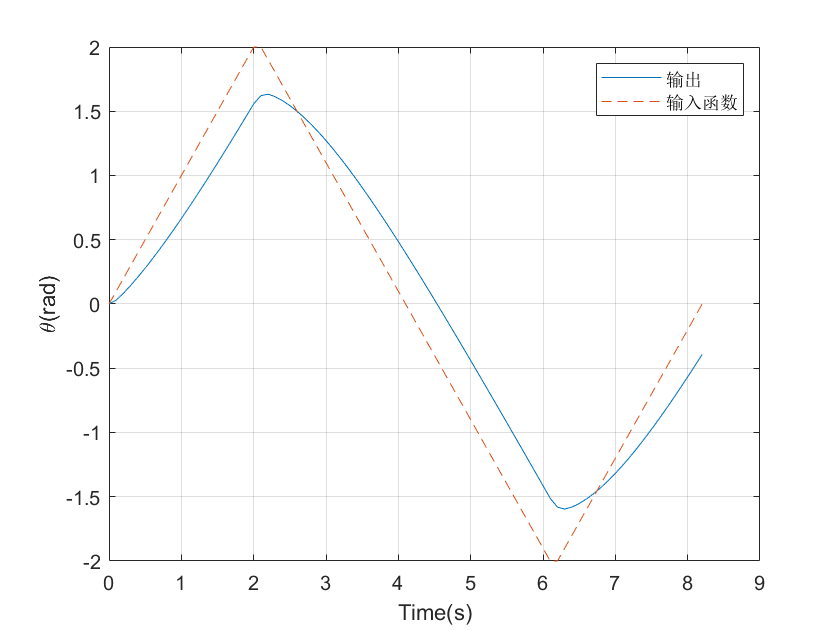

[y, T] = lsim(sys,u,t);
plot(T,y,t,u,'--');
xlabel('Time(s)');
ylabel('\theta(rad)');
grid on
legend('输出','输入函数')

clear
t = [0:0.01:10]

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


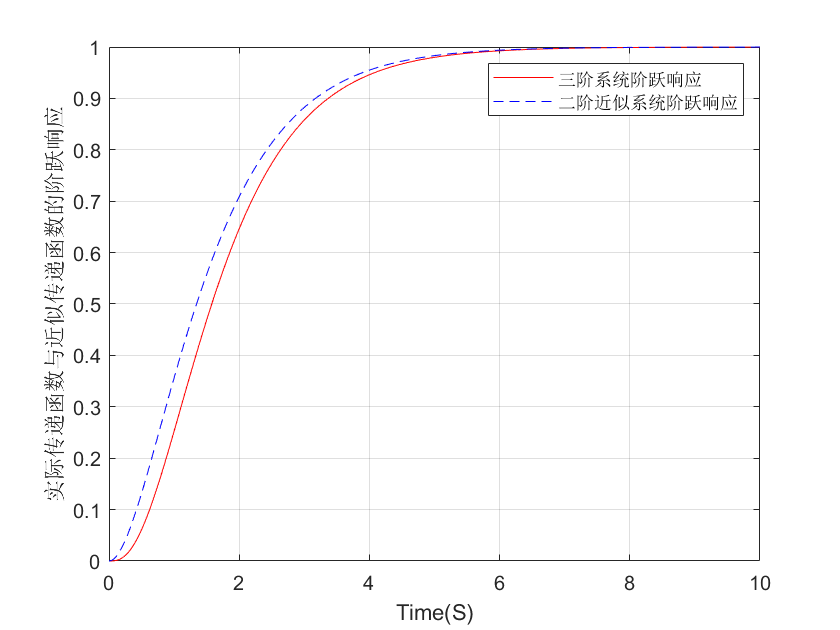

num1 = [6];
den1 = [1 6 11 6];
sys1 = tf(num1,den1);

num2 = [1.6];
den2 = [1 2.59 1.6];
sys2 = tf(num2,den2);
[y1,T1] = step(sys1,t);
[y2,T2] = step(sys2,t);
plot(T1,y1,'r-',T2,y2,'b--')
grid on
xlabel('Time(S)');
ylabel('实际传递函数与近似传递函数的阶跃响应');
legend('三阶系统阶跃响应','二阶近似系统阶跃响应');

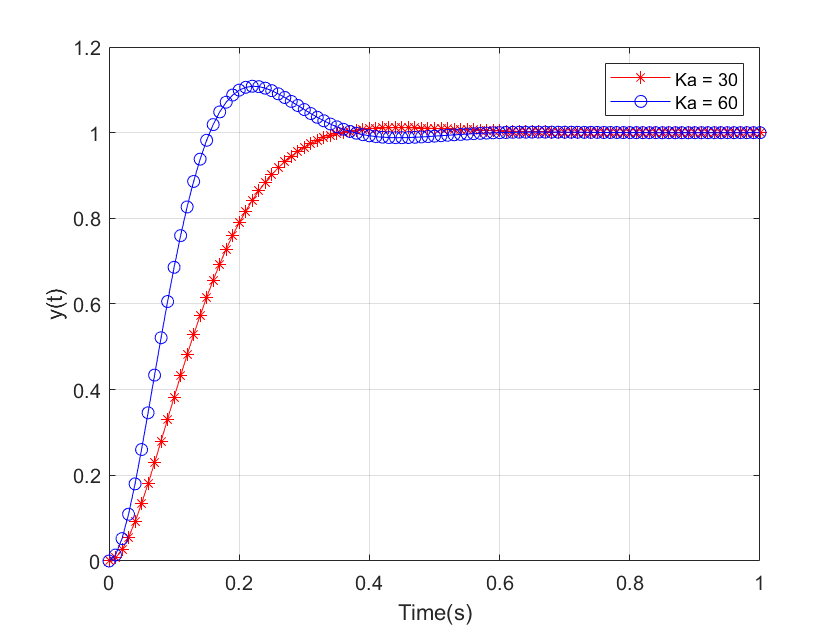

clear
Ka = 30;
t = [0:0.01:1];
nc = [Ka*5];
dc = [1];
sysc = tf(nc,dc);
ng = [1];
dg = [1 20 0];
sysg = tf(ng,dg);
sys1 = series(sysc,sysg);
sys = feedback(sys1,[1]);
y = step(sys,t);
plot(t,y,'r-*'),grid on;
xlabel('Time(s)'),ylabel('y(t)');

Ka = 60;
t = [0:0.01:1];
nc = [Ka*5];
dc = [1];
sysc = tf(nc,dc);
ng = [1];
dg = [1 20 0];
sysg = tf(ng,dg);
sys1 = series(sysc,sysg);
sys = feedback(sys1,[1]);
y = step(sys,t);
hold on;
plot(t,y,'b-o'),grid on;
legend('Ka = 30','Ka = 60')
hold off

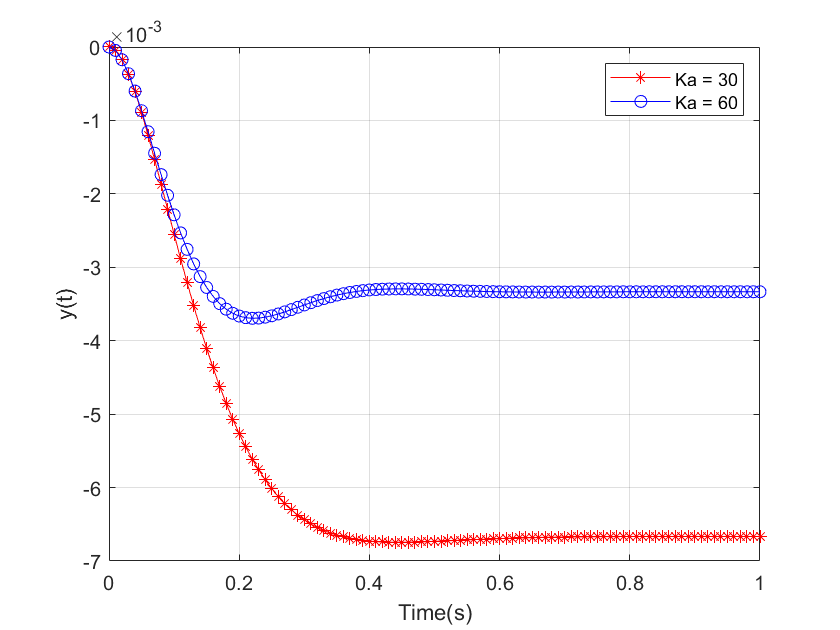

clear
Ka = 30;
t = [0:0.01:1];
nc = [Ka*5];
dc = [1];
sysc = tf(nc,dc);
ng = [1];
dg = [1 20 0];
sysg = tf(ng,dg);
sys = feedback(sysg,sysc);
sys = -sys;
y = step(sys,t);
plot(t,y,'r-*');
grid on;
xlabel('Time(s)');
ylabel('y(t)');
hold on
Ka = 60;
t = [0:0.01:1];
nc = [Ka*5];
dc = [1];
sysc = tf(nc,dc);
ng = [1];
dg = [1 20 0];
sysg = tf(ng,dg);
sys = feedback(sysg,sysc);
sys = -sys;
y = step(sys,t);
plot(t,y,'b-o');
legend('Ka = 30','Ka = 60')
hold off